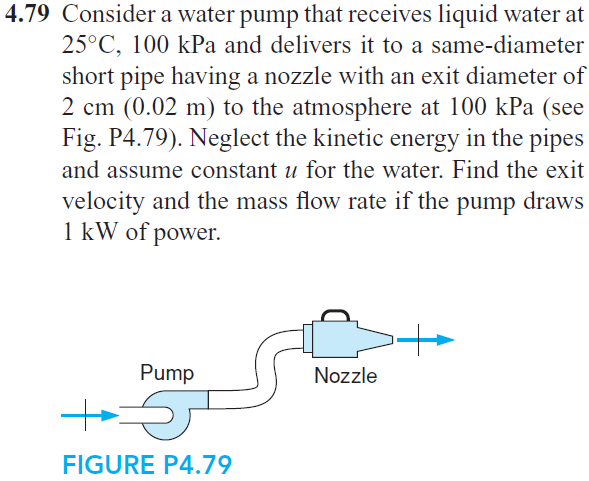

# symbolic units class

u = symunit;
old_assum = assumptions;
clearassum;

# state 1 (saturated liquid water)

% --------------
% given
p1 = 100*u.kPa;
T1 = 25*u.Celsius;
D1 = 2*u.cm;
V1 = 0;
% --------------
% specific volume
v1 = 0.001003*u.m^3/u.kg;
% --------------
% area
A1 = sympi*D1^2/4;
% --------------
% mass flow rate
mdot1 = sym('mdot1');
% --------------

# state 2 (saturated liquid water)

% --------------
% given
p2 = 100*u.kPa;
T2 = 25*u.Celsius;
D2 = D1;
V2 = sym('V2', 'positive');
% --------------
% specific volume
v2 = 0.001003*u.m^3/u.kg;
% --------------
% area
A2 = sympi*D2^2/4;
% --------------
% mass flow rate
mdot2(V2) = rewrite(A2*V2/v2, 'SI');
% --------------

# conservation of mass

eqn = sym.zeros(2,1);
eqn(1) = mdot1 == mdot2;

# conservation of energy

Wdot = -1*u.kW;
eqn(2) = mdot1*(p1*v1+V1^2/2) == mdot2*(p2*v2+V2^2/2)+Wdot;

# solution

[V2 mdot1] = solve(eqn, [V2 mdot1]); %#ok
V2 = simplify(V2);
V2_vpa = vpa(V2, 4) %#ok

$$V2\_vpa = 18.55\,\frac{m}{s}$$

mdot1 = simplify(rewrite(mdot1, 'SI'));
mdot1_vpa = vpa(mdot1, 3) %#ok

$$mdot1\_vpa = 5.81\,\frac{\mathrm{kg}}{s}$$

clear V2_vpa mdot1_vpa;
setassum(old_assum);